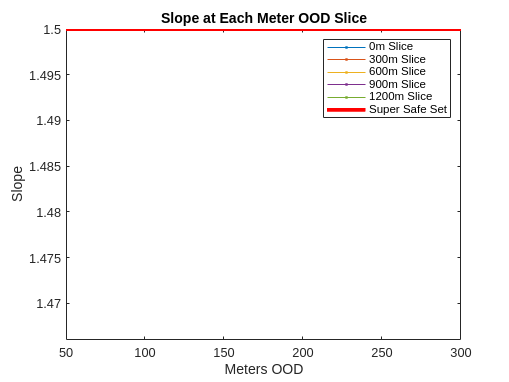

clear variables; close all; clc;

%Take "generated states" and "combined states" tables and combine them
function data = grabData(data_g, data_c)
    data = table;
    data.error_NN_h = data_c.error_h; %NN Error, height offset 
    data.error_NN_y = data_c.error_y; %NN Error, crosstrack offset 
    data.y_pred = data_g.y_err; %NN Output- Predicted crosstrack offset 
    data.h_pred = data_g.h_err_NN; %NN Output- Predicted height offset
    data.h_true = data_g.h_err_true; %True height error based on state info 

    %True State Information 
    data.y = data_c.y; %True crosstrack position and error
    data.x = data_c.x; %Horizontal distance from runway 
    data.h = data_c.h; %True Height (Altitude relative to runway) 
end

%Get a "slice" of data from a given x-distance from runway
function slices = grabSlice(data, start, endpoint)
    rows = data.x > start & data.x <= endpoint;
    slices = data(rows,:);
end

%Get all data in a range of OOD values from min_dist to max_dist
function ood = grabOOD(data, min_dist, max_dist)
    rows = data.y > min_dist & data.y <= max_dist;
    ood = data(rows,:);
end

%Combine all OOD tables for a slice into one array
function [ood_50, ood_100, ood_150, ood_200, ood_250, ood_300] = combOOD(data)
    ood_50 = grabOOD(data, 0, 50);
    ood_100 = grabOOD(data, 50, 100);
    ood_150 = grabOOD(data, 100, 150);
    ood_200 = grabOOD(data, 200, 250);
    ood_250 = grabOOD(data, 250, 300);
    ood_300 = grabOOD(data, 300, 350);
end

%Calculate the slope of (ehat - e) over ehat for every OOD section
function slopes = getSlopes(data_arr)
    slopes = zeros(numel(data_arr), 1);
    for i = 1:numel(data_arr)
        data = data_arr{i};
        p = polyfit(data.error_NN_y, data.y_pred, 1);
        slopes(i) = p(1);
    end
end

safe_slices_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/safe/2024-7-23/generated_states.csv");
safe_slices_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/safe/2024-7-23/combined_states.csv");
safe_slices = grabData(safe_slices_g, safe_slices_c);

unsafe_slices_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/unsafe/2024-7-23/generated_states.csv");
unsafe_slices_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/unsafe/2024-7-23/combined_states.csv");
unsafe_slices = grabData(unsafe_slices_g, unsafe_slices_c);

%Get each 'slice' of data from safe set
safe_slice_0 = grabSlice(safe_slices, 0, 300);
safe_slice_300 = grabSlice(safe_slices, 300, 600);
safe_slice_600 = grabSlice(safe_slices, 600, 900);
safe_slice_900 = grabSlice(safe_slices, 900, 1200);
safe_slice_1200 = grabSlice(safe_slices, 1200, 1500);

all_ood_g = readtable("/media/storage_drive/ULI Datasets/OOD Data/dataWPI_350-15_sliced/generated_states.csv");
all_ood_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-25/350/combined_states.csv");
all_ood = grabData(all_ood_g, all_ood_c);

%Get all combinations of meters OOD and slice distance from runway
%Format is ood_(slice distance)_(meters OOD)
[ood_0_50, ood_0_100, ood_0_150, ood_0_200, ood_0_250, ood_0_300] = combOOD(grabSlice(all_ood, 0, 300));
[ood_300_50, ood_300_100, ood_300_150, ood_300_200, ood_300_250, ood_300_300] = combOOD(grabSlice(all_ood, 300, 600));
[ood_600_50, ood_600_100, ood_600_150, ood_600_200, ood_600_250, ood_600_300] = combOOD(grabSlice(all_ood, 600, 900));
[ood_900_50, ood_900_100, ood_900_150, ood_900_200, ood_900_250, ood_900_300] = combOOD(grabSlice(all_ood, 900, 1200));
[ood_1200_50, ood_1200_100, ood_1200_150, ood_1200_200, ood_1200_250, ood_1200_300] = combOOD(grabSlice(all_ood, 1200, 1500));

%Get all slopes for OOD values. Safe set has constant slope of 1.5
slope_0 = getSlopes({ood_0_50, ood_0_100, ood_0_150, ood_0_200, ood_0_250, ood_0_300});
slope_300 = getSlopes({ood_300_50, ood_300_100, ood_300_150, ood_300_200, ood_300_250, ood_300_300});
slope_600 = getSlopes({ood_600_50, ood_600_100, ood_600_150, ood_600_200, ood_600_250, ood_600_300});
slope_900 = getSlopes({ood_900_50, ood_900_100, ood_900_150, ood_900_200, ood_900_250, ood_900_300});
slope_1200 = getSlopes({ood_1200_50, ood_1200_100, ood_1200_150, ood_1200_200, ood_1200_250, ood_1200_300});
all_slopes = [slope_0; slope_300; slope_600; slope_900; slope_1200];

%Plot all slopes 
dists = [50, 100, 150, 200, 250, 300];
plot(dists, slope_0, 'Marker', ".");
hold on;
plot(dists, slope_300, 'Marker', ".");
plot(dists, slope_600, 'Marker', ".");
plot(dists, slope_900, 'Marker', ".");
plot(dists, slope_1200, 'Marker', ".");
plot(dists, repelem(1.5, length(dists)), 'LineWidth', 3, 'Color', "Red");
xlabel("Meters OOD");
ylabel("Slope");
title("Slope at Each Meter OOD Slice");
legend({"0m Slice", "300m Slice", "600m Slice", "900m Slice", "1200m Slice", "Super Safe Set"}, 'Location', 'northeast');
hold off;

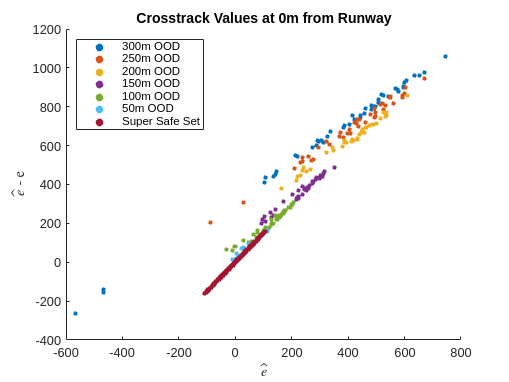


size = 10;

%Slice taken at 0m from runway
scatter(ood_0_300.error_NN_y, (ood_0_300.y_pred), size, 'filled');
hold on;
scatter(ood_0_250.error_NN_y, (ood_0_250.y_pred), size, 'filled');
scatter(ood_0_200.error_NN_y, (ood_0_200.y_pred), size, 'filled');
scatter(ood_0_150.error_NN_y, (ood_0_150.y_pred), size, 'filled');
scatter(ood_0_100.error_NN_y, (ood_0_100.y_pred), size, 'filled');
scatter(ood_0_50.error_NN_y, (ood_0_50.y_pred), size, 'filled');
scatter(safe_slice_0.error_NN_y, (safe_slice_0.y_pred), size, 'filled');
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values at 0m from Runway");
legend({"300m OOD", "250m OOD", "200m OOD", "150m OOD", "100m OOD", "50m OOD", "Super Safe Set"}, 'Location', 'northwest');
hold off;

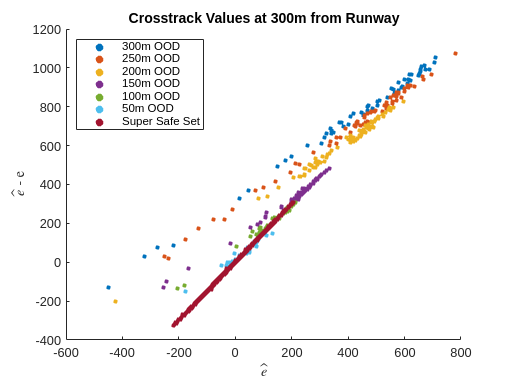


%Slice taken at 300m from runway
scatter(ood_300_300.error_NN_y, (ood_300_300.y_pred), size, 'filled');
hold on;
scatter(ood_300_250.error_NN_y, (ood_300_250.y_pred), size, 'filled');
scatter(ood_300_200.error_NN_y, (ood_300_200.y_pred), size, 'filled');
scatter(ood_300_150.error_NN_y, (ood_300_150.y_pred), size, 'filled');
scatter(ood_300_100.error_NN_y, (ood_300_100.y_pred), size, 'filled');
scatter(ood_300_50.error_NN_y, (ood_300_50.y_pred), size, 'filled');
scatter(safe_slice_300.error_NN_y, (safe_slice_300.y_pred), size, 'filled');
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values at 300m from Runway");
legend({"300m OOD", "250m OOD", "200m OOD", "150m OOD", "100m OOD", "50m OOD", "Super Safe Set"}, 'Location', 'northwest');
hold off;

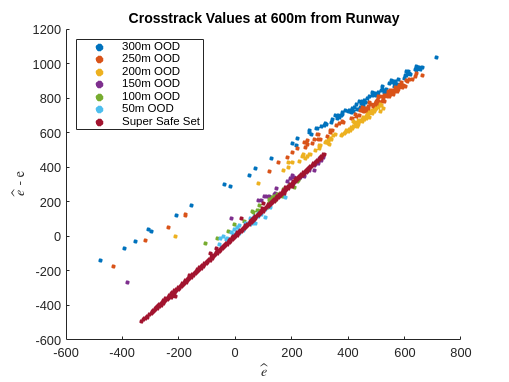


%Slice taken at 600m from runway
scatter(ood_600_300.error_NN_y, (ood_600_300.y_pred), size, 'filled');
hold on;
scatter(ood_600_250.error_NN_y, (ood_600_250.y_pred), size, 'filled');
scatter(ood_600_200.error_NN_y, (ood_600_200.y_pred), size, 'filled');
scatter(ood_600_150.error_NN_y, (ood_600_150.y_pred), size, 'filled');
scatter(ood_600_100.error_NN_y, (ood_600_100.y_pred), size, 'filled');
scatter(ood_600_50.error_NN_y, (ood_600_50.y_pred), size, 'filled');
scatter(safe_slice_600.error_NN_y, (safe_slice_600.y_pred), size, 'filled');
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values at 600m from Runway");
legend({"300m OOD", "250m OOD", "200m OOD", "150m OOD", "100m OOD", "50m OOD", "Super Safe Set"}, 'Location', 'northwest');
hold off;

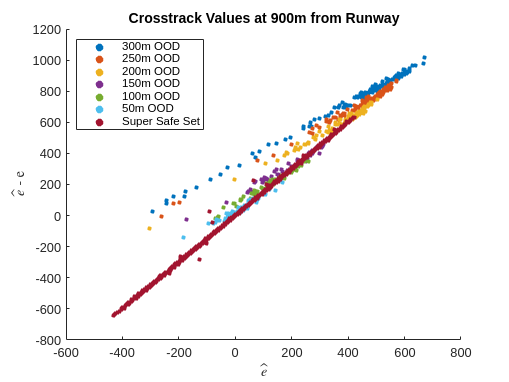


%Slice taken at 900m from runway
scatter(ood_900_300.error_NN_y, (ood_900_300.y_pred), size, 'filled');
hold on;
scatter(ood_900_250.error_NN_y, (ood_900_250.y_pred), size, 'filled');
scatter(ood_900_200.error_NN_y, (ood_900_200.y_pred), size, 'filled');
scatter(ood_900_150.error_NN_y, (ood_900_150.y_pred), size, 'filled');
scatter(ood_900_100.error_NN_y, (ood_900_100.y_pred), size, 'filled');
scatter(ood_900_50.error_NN_y, (ood_900_50.y_pred), size, 'filled');
scatter(safe_slice_900.error_NN_y, (safe_slice_900.y_pred), size, 'filled');
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values at 900m from Runway");
legend({"300m OOD", "250m OOD", "200m OOD", "150m OOD", "100m OOD", "50m OOD", "Super Safe Set"}, 'Location', 'northwest');
hold off;

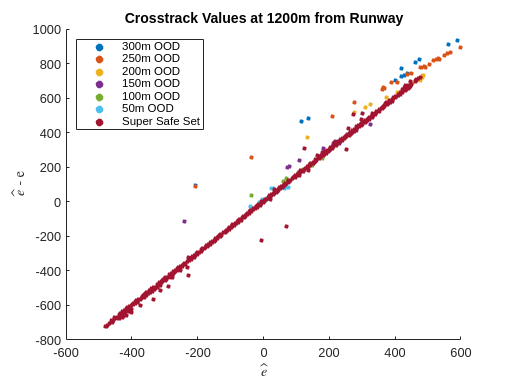


%Slice taken at 1200m from runway
scatter(ood_1200_300.error_NN_y, (ood_1200_300.y_pred), size, 'filled');
hold on;
scatter(ood_1200_250.error_NN_y, (ood_1200_250.y_pred), size, 'filled');
scatter(ood_1200_200.error_NN_y, (ood_1200_200.y_pred), size, 'filled');
scatter(ood_1200_150.error_NN_y, (ood_1200_150.y_pred), size, 'filled');
scatter(ood_1200_100.error_NN_y, (ood_1200_100.y_pred), size, 'filled');
scatter(ood_1200_50.error_NN_y, (ood_1200_50.y_pred), size, 'filled');
scatter(safe_slice_1200.error_NN_y, (safe_slice_1200.y_pred), size, 'filled');
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values at 1200m from Runway");
legend({"300m OOD", "250m OOD", "200m OOD", "150m OOD", "100m OOD", "50m OOD", "Super Safe Set"}, 'Location', 'northwest');
hold off;



% scatter(all_ood.error_NN_y, (all_ood.y_pred), size, "filled");
% hold on;
% scatter(unsafe_slices.error_NN_y, (unsafe_slices.y_pred), size, "red", "filled");
% scatter(safe_slices.error_NN_y, (safe_slices.y_pred), size, "green", "filled");
% xlabel('$$\hat{e}$$','Interpreter','Latex');
% ylabel('$\hat{e}$ - e','Interpreter','Latex');
% title("Crosstrack Values");
% legend({"OOD", "'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
% hold off;
% 
% scatter3(all_ood.y_pred, all_ood.error_NN_y, all_ood.x);
% hold on;
% scatter3(safe_slices.y_pred, safe_slices.error_NN_y, safe_slices.x);
% xlabel('$\hat{e}$ - e','Interpreter','Latex');
% ylabel('$$\hat{e}$$','Interpreter','Latex');
% zlabel("Dist from runway");
% hold off;
% 
% scatter3(all_ood.y_pred, all_ood.error_NN_y, all_ood.y);
% hold on;
% scatter3(safe_slices.y_pred, safe_slices.error_NN_y, safe_slices.y);
% xlabel('$\hat{e}$ - e','Interpreter','Latex');
% ylabel('$$\hat{e}$$','Interpreter','Latex');
% zlabel("Dist from Glidescope");
% hold off;